# Payload Path Planning

Daniel Pearson - 1/5/2024

clear variables; close all; clc;

## Constants

% % First Point in path
% x1 = 0;
% y1 = 0;
% 
% % Second Point in path
% x2 = 10;
% y2 = 10;

x_pts = [0; 5000];
y_pts = [20; 40];

## Curve Fitting

Using the least squares estimation method, the constants in the following equation can be estimated with reasonable accuracy


$$y={\textrm{Ax}}^3 +{\textrm{Bx}}^2 +\textrm{Cx}+D$$


Using the theory of least squares estimation, the following can be defined:


$$\sum^{2}_{i=1}(y_i-(Ax_i^4+Bx_i^3+Cx_i^2+Dx_i+E))^2$$


This summation can be minimized and the following matrices can be defined to solve for C


$$\begin{array}{l}
X=\left\lbrack \begin{array}{cccc}
x^3  & x^2  & x & 1
\end{array}\right\rbrack \\
Y=\left\lbrack \begin{array}{c}
y_1 \\
\vdots \\
y_i 
\end{array}\right\rbrack \\
C=\left\lbrack \begin{array}{c}
A\\
B\\
C\\
D
\end{array}\right\rbrack 
\end{array}$$


where,


$$X^T Y=X^T \textrm{XC}$$


X = [x_pts.^3, x_pts.^2, x_pts, ones(size(x_pts))];

% Use least squares estimate to solve for C
C = X \ y_pts;

### Display Curve

syms x;
% cubic_function = C(1)*x^4 + C(2)*x^3 + C(3)*x^2 + C(4)*x + C(5)
cubic_function = C(1)*x^3 + C(2)*x^2 + C(3)*x + C(4)

$$cubic\_function = \frac{6189700196426901\,x^{3}}{38685626227668133590597632}+20$$

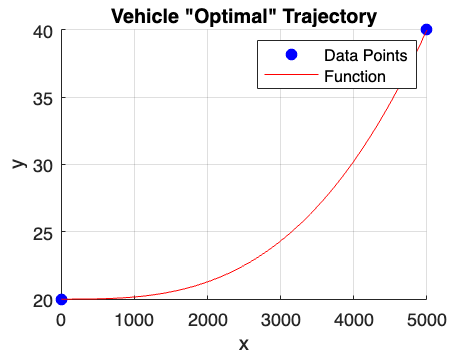


figure;
scatter(x_pts, y_pts, 'o', 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b');
hold on;
fplot(cubic_function, [min(x_pts), max(x_pts)], 'r');
title('Vehicle "Optimal" Trajectory');
xlabel('x');
ylabel('y');
legend('Data Points', 'Function');
grid on;